%Generacja systemu
r_min=-5;
r_max=5;
r=(r_min-r_max).*rand()+r_max;
b0=2*r;
r=(r_min-r_max).*rand()+r_max;
a0=2*r;
r=(r_min-r_max).*rand()+r_max;
a1=2*r;
r=(r_min-r_max).*rand()+r_max;
a2=2*r;
r=(r_min-r_max).*rand()+r_max;
a3=2*r;

a3=1;
a2=6;
a1=2;
a0=1;
b0=1;

L=[b0];
M=[a3 a2 a1 a0];
sys=tf(L,M)


sys =
 
            1
  ---------------------
  s^3 + 6 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


[A, B, C, D]=tf2ss(L,M)

A =     -6    -2    -1
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     0     1


D = 0

% norm(A,"fro")
% step(sys,0:0.1:30);

%Toeplitz
H1=1/a3*[a1 a2 a3 0; a2 a3 0 0; a3 0 0 0]

H1 =      2     6     1     0
     6     1     0     0
     1     0     0     0


H2=1/a3*[b0 0 0 0; 0 0 0 0; 0 0 0 0]

H2 =      1     0     0     0
     0     0     0     0
     0     0     0     0


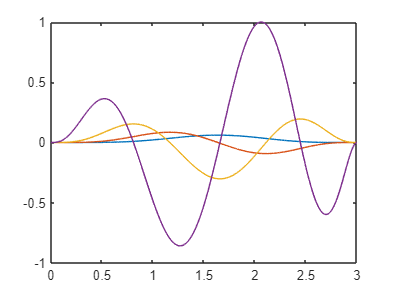

%funkcja phi /znormalizować
h=3;
step_size=0.001;
t=0:step_size:h;
N=6;
M=5;
% global phi phi_1 phi_2;
phi=(t.^N).*((h-t).^M);

% phi_1=diff(phi)/step_size;
phi_1=(N*t.^(N-1)).*((h-t).^M)-(M*t.^N).*(h-t).^(M-1);

% phi_2=diff(phi_1)/step_size;
phi_2=(M*t.^N).*((h-t).^(M-2)).*(M-1)-(2*M*N*t.^(N-1)).*((h-t).^(M-1))+(N*t.^(N-2).*((h-t).^M)*(N-1));

phi_3=3*M*N*t.^(N - 1).*(h - t).^(M - 2).*(M - 1) - M*t.^N.*(h - t).^(M - 3).*(M - 1).*(M - 2) - 3*M*N*t.^(N - 2).*(h - t).^(M - 1).*(N - 1) + N*t.^(N - 3).*(h - t).^M.*(N - 1).*(N - 2); 
phi=phi/max(abs(phi_3));
phi_1=phi_1/max(abs(phi_3));
phi_2=phi_2/max(abs(phi_3));
phi_3=phi_3/max(abs(phi_3));
plot(t,phi,t,phi_1,t,phi_2,t,phi_3)

trapz(t,phi,2)

ans = 0.0646

trapz(t,phi_1,2)

ans = -2.3187e-18

trapz(t,phi_2,2)

ans = 8.1883e-14

trapz(t,phi_3,2)

ans = 1.1463e-12

conv_size=length(phi);
T_iD=7/step_size;

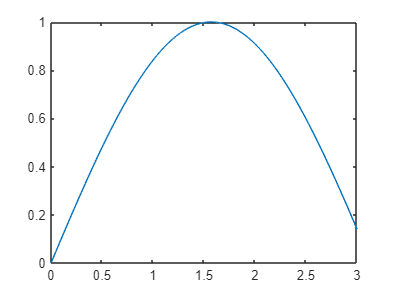

plot(t,sin(t))

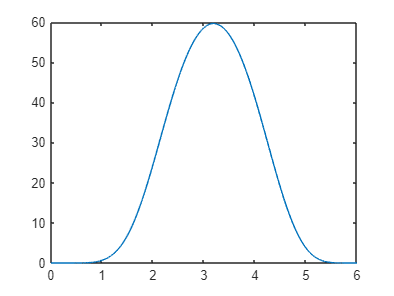

% plot(t,cumtrapz(t,sin(t)))
vec=0:step_size:(length(conv(sin(t),phi))-1)*step_size;
conv_plot=conv(sin(t),phi);
plot(vec,conv_plot)

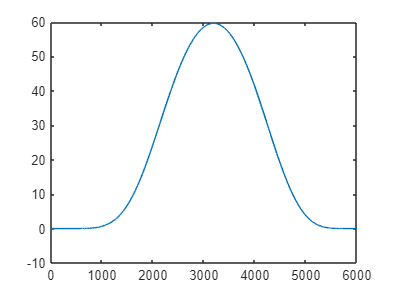

clear splot_1 splot_2
sinus=sin(t);
for j=1:length(sinus)+length(phi)-2
    clear splot_1
    if j<=length(sinus)        
        splot_1=sinus(1:j).*fliplr(phi(1:j));        
    else
        splot_1=sinus((j-length(sinus)):end).*fliplr(phi((j-length(sinus)):end));
    end
    splot_2(j)=trapz([0:step_size:(length(splot_1)-1)*step_size],splot_1,2);
end
SINUS=fft([sinus zeros(1,length(phi)-1)]);
PHI=fft([phi zeros(1,length(sinus)-1)]);
plot(ifft(SINUS.*PHI))

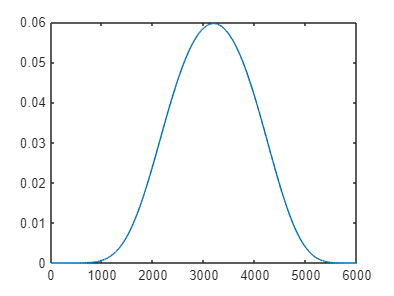

% plot(splot_1)
% xlim([0 400])
plot(splot_2)

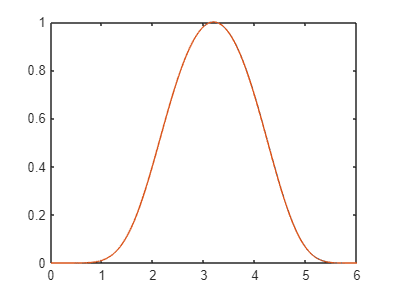

plot(vec(1:end-1),splot_2/max(splot_2),vec,conv_plot/max(conv_plot))

% xlim([0 400])
% plot(vec,conv(sin(t),phi_1))
% plot(cumtrapz(vec,conv(sin(t),phi),2))
% plot(vec,cumtrapz(vec,conv(sin(t),phi_1),2)*4.25,vec,conv(sin(t),phi))

%Regulator
K=[0.1 0.1 0.1];
Ac=A-B*K;
Q=[1 0 0;
   0 1 0;
   0 0 1];
[K, S, poles]=lqr(A,B,Q,[0.01])

K =     7.0237   16.8089    9.0499


S =     0.0702    0.1681    0.0905
    0.1681    2.2391    1.2489
    0.0905    1.2489    1.8703


poles =   -0.7824 + 0.5146i
  -0.7824 - 0.5146i
 -11.4588 + 0.0000i


K=K/20000

K = 1.0e-03 *

    0.3512    0.8404    0.4525


syms t N h M
phi_anal(t) = (t^N)*((h-t)^M);
phi_anal1(t)=diff(phi_anal,t)
phi_anal2(t)=diff(phi_anal1,t)
phi_anal3(t)=diff(phi_anal2,t)

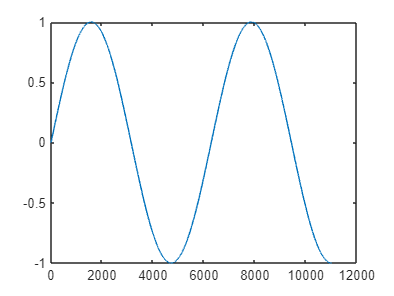

%simulate system
x0 = [0;0;0];             % Initial state (N=2)
Ns = 11/step_size; 	    % Number of sample times to simulate
u = sin(0:step_size:(Ns-1)*step_size); % Input signal (an impulse at time 0)
y = zeros(Ns,1);        % Preallocate output signal for n=0:Ns-1

% Perform the system simulation:
x = x0;                % Set initial state
x_p = x0;
for n=1:Ns-1           % Iterate through time
  y(n) = C*x_p + D*u(n); % Output for time n-1
  x(:,end) = A*x_p + B*u(n);    % State transitions to time n
  x = [x [0;0;0]];
  x_p = trapz([0:step_size:(size(x,2)-2)*step_size],x(:,1:end-1),2);
end
plot(u)

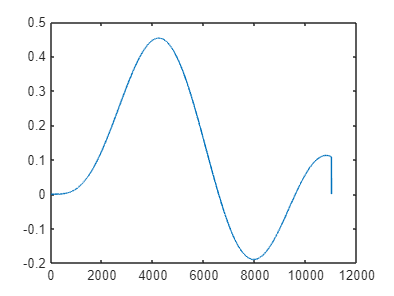

plot(y)

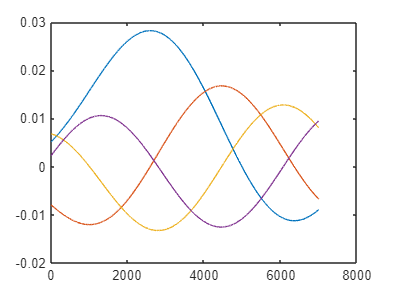

%evaluate method
t_=0:step_size:((conv_size-1)*step_size);
for n=1:T_iD-conv_size
    y0(n)=trapz(t_,(y(n:conv_size-1+n).*flipud(phi)'),1);
    y1(n)=trapz(t_,(y(n:conv_size-1+n).*flipud(phi_1)'),1);
    y2(n)=trapz(t_,(y(n:conv_size-1+n).*flipud(phi_2)'),1);
    y3(n)=trapz(t_,(y(n:conv_size-1+n).*flipud(phi_3)'),1);
    
    u0(n)=trapz(t_,(u(n:conv_size-1+n).*flipud(phi)),2);
    u1(n)=trapz(t_,(u(n:conv_size-1+n).*flipud(phi_1)),2);
    u2(n)=trapz(t_,(u(n:conv_size-1+n).*flipud(phi_2)),2);
    u3(n)=trapz(t_,(u(n:conv_size-1+n).*flipud(phi_3)),2);
end
plot(y0)
hold on
plot(y1)
plot(y2)
plot(y3)
hold off

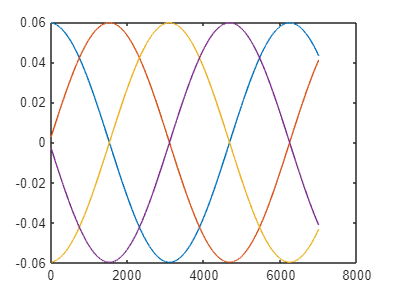

plot(u0)
hold on
plot(u1)
plot(u2)
plot(u3)
hold off

%macierz Gramma
t=0:step_size:((length(y0)-1)*step_size);
        g11=trapz(t,y0.*y0,2);
        g12=trapz(t,y0.*y1,2);
        g13=trapz(t,y0.*y2,2);
        g14=trapz(t,y0.*y3,2);
        g15=trapz(t,y0.*u0,2);
        g16=trapz(t,y0.*u1,2);
        g17=trapz(t,y0.*u2,2);
        g18=trapz(t,y0.*u3,2);
        
%         g21=trapz(t,y1.*y0,1);
        g22=trapz(t,y1.*y1,2);
        g23=trapz(t,y1.*y2,2);
        g24=trapz(t,y1.*y3,2);
        g25=trapz(t,y1.*u0,2);
        g26=trapz(t,y1.*u1,2);
        g27=trapz(t,y1.*u2,2);
        g28=trapz(t,y1.*u3,2);
        
%         g31=trapz(t,y2.*y0,1);
%         g32=trapz(t,y2.*y1,1);
        g33=trapz(t,y2.*y2,2);
        g34=trapz(t,y2.*y3,2);
        g35=trapz(t,y2.*u0,2);
        g36=trapz(t,y2.*u1,2);
        g37=trapz(t,y2.*u2,2);
        g38=trapz(t,y2.*u3,2);
        
%         g41=trapz(t,y3.*y0,1);
%         g42=trapz(t,y3.*y1,1);
%         g43=trapz(t,y3.*y2,1);
        g44=trapz(t,y3.*y3,2);
        g45=trapz(t,y3.*u0,2);
        g46=trapz(t,y3.*u1,2);
        g47=trapz(t,y3.*u2,2);
        g48=trapz(t,y3.*u3,2);
        
%         g51=trapz(t,u0.*y0,1);
%         g52=trapz(t,u0.*y1,1);
%         g53=trapz(t,u0.*y2,1);
%         g54=trapz(t,u0.*y3,1);
        g55=trapz(t,u0.*u0,2);
        g56=trapz(t,u0.*u1,2);
        g57=trapz(t,u0.*u2,2);
        g58=trapz(t,u0.*u3,2);
        
        % g61=trapz(t,u1.*y0,1);
        % g62=trapz(t,u1.*y1,1);
        % g63=trapz(t,u1.*y2,1);
        % g64=trapz(t,u1.*y3,1);
        % g65=trapz(t,u1.*u0,1);
        g66=trapz(t,u1.*u1,2);
        g67=trapz(t,u1.*u2,2);
        g68=trapz(t,u1.*u3,2);
        % 
        % g71=trapz(t,u2.*y0,1);
        % g72=trapz(t,u2.*y1,1);
        % g73=trapz(t,u2.*y2,1);
        % g74=trapz(t,u2.*y3,1);
        % g75=trapz(t,u2.*u0,1);
        % g76=trapz(t,u2.*u1,1);
        g77=trapz(t,u2.*u2,2);
        g78=trapz(t,u2.*u3,2);
        % 
        % g81=trapz(t,u3.*y0,1);
        % g82=trapz(t,u3.*y1,1);
        % g83=trapz(t,u3.*y2,1);
        % g84=trapz(t,u3.*y3,1);
        % g85=trapz(t,u3.*u0,1);
        % g86=trapz(t,u3.*u1,1);
        % g87=trapz(t,u3.*u2,1);
        g88=trapz(t,u3.*u3,2);
        
        G=[g11 g12 g13 g14 -g15 -g16 -g17 -g18;
           g12 g22 g23 g24 -g25 -g26 -g27 -g28;
           g13 g23 g33 g34 -g35 -g36 -g37 -g38;
           g14 g24 g34 g44 -g45 -g46 -g47 -g48;
           -g15 -g25 -g35 -g45 g55 g56 g57 g58;
           -g16 -g26 -g36 -g46 g56 g66 g67 g68;
           -g17 -g27 -g37 -g47 g57 g67 g77 g78;
           -g18 -g28 -g38 -g48 g58 g68 g78 g88]

G =     0.0021   -0.0000   -0.0009    0.0001    0.0031   -0.0016   -0.0031    0.0016
   -0.0000    0.0008    0.0000   -0.0006    0.0009    0.0027   -0.0009   -0.0027
   -0.0009    0.0000    0.0006   -0.0000   -0.0025    0.0007    0.0025   -0.0007
    0.0001   -0.0006   -0.0000    0.0005   -0.0007   -0.0022    0.0007    0.0022
    0.0031    0.0009   -0.0025   -0.0007    0.0132    0.0008   -0.0132   -0.0008
   -0.0016    0.0027    0.0007   -0.0022    0.0008    0.0116   -0.0008   -0.0116
   -0.0031   -0.0009    0.0025    0.0007   -0.0132   -0.0008    0.0132    0.0008
    0.0016   -0.0027   -0.0007    0.0022   -0.0008   -0.0116    0.0008    0.0116


[V, D]=eig(G)

V =     0.0355   -0.1492   -0.0068   -0.0818    0.1181   -0.9555   -0.1630    0.1273
   -0.0709    0.2980    0.0136   -0.0230   -0.9215   -0.1720    0.1350    0.0917
    0.2128   -0.8947   -0.0409   -0.1516   -0.3171    0.0912    0.0918   -0.1112
   -0.0353    0.1483    0.0068   -0.9758    0.0379    0.0729   -0.1113   -0.0731
   -0.0329   -0.0544   -0.7084   -0.0249   -0.0197    0.1377   -0.2301    0.6490
    0.6861    0.1650   -0.0446   -0.0904    0.1304   -0.0539    0.6436    0.2401
   -0.0684    0.0948   -0.7016    0.0249    0.0197   -0.1377    0.2301   -0.6490
    0.6860    0.1655   -0.0445    0.0904   -0.1304    0.0539   -0.6436   -0.2401


D =    -0.0000         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0
         0         0    0.0000         0         0         0         0         0
         0         0         0    0.0000         0         0         0         0
         0         0         0         0    0.0001         0         0         0
         0         0         0         0         0    0.0011         0         0
         0         0         0         0         0         0    0.0241         0
         0         0         0         0         0         0         0    0.0284


I=[0 0 0 0 0 0 0 0];
        M=[1e6 1e6 1e6 1e6 1e6 1e6 1e6 1e6];
        D=real(D);
        V=real(V);
        for j=1:length(D)
            for i=1:length(D)
                if i==j
                    M(j)=D(i,j);
                    I(j)=i;
                end
            end
        end
        ind=1;
        temp_min=1e6;
        for i=1:length(M)
            if  M(i)<temp_min %&& abs(M(i))>1e-10 
                ind=i;
                temp_min=M(ind);
            end
        end
oa=[V(4,ind) V(3,ind) V(2,ind) V(1,ind)]'

oa =    -0.0353
    0.2128
   -0.0709
    0.0355


ob=[V(8,ind) V(7,ind) V(6,ind) V(5,ind)]'

ob =     0.6860
   -0.0684
    0.6861
   -0.0329
